# Example: Acoustics in 1D, Time Series Data

This live-script features the following:

- 1D example

- how to generate time series data

- different visualizations

- visualizing point source and receiver locations

- plotTimeSeries for solutions

In real world applications, the pressure field (or the other fields) is only sampled at a discrete and small number of spatial locations where receivers are placed. Here we give examples on how to simulate data "recorded" at receiver locations.

clear

domain_x = [0,1];
domain_t = [0,1.5];

% Computational grids and grid spaces
Nx = 401;
grid_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_dual   = Grid1DUnifDual(grid_primal);
gridSp_P    = GridSpace1D(grid_primal);
gridSp_V    = GridSpace1D(grid_dual);
dx = gridSp_P.h;

% Acoustic medium parameters
medium = AcousticMedium1D.layered( ...
    BetaValues=[0.25,0.5,1], ...
    KappaValues=[4,3,8], ...
    Domain=domain_x, ...
    RelativeWidths=[0.2,0.5,0.3]);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gridSp_P,medium);

% Computational time grid
CFL = 0.9;
dt = CFL*(6/7)*dx/cMax;
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output times
t_pts_out = linspace(domain_t(1),domain_t(2),101);

% Initializing PML
pml = PML1D(WidthLeft=0.2,WidthRight=0.2);

% Zero initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

Here we specify a multipole source with two terms centered at different locations.

% Multipole point source
x0 = 0.8;
s0 = 0;
w0 = @(t) RickerWave(t,0.2,10);
monopole = MultipoleComponent1D(x0,s0,TargetField="pressure");
mps0 = MultipoleSrcTerm1D(monopole,w0);

x1 = 0.75;
s1 = 1;
w1 = @(t) dx*10*exp(-(t-0.2).^2/0.025^2);
dipole = MultipoleComponent1D(x1,s1,TargetField="pressure");
mps1 = MultipoleSrcTerm1D(dipole,w1);

mps = MultipoleSrcSeries1D([mps0,mps1]);
appxOrder = 4;
source = mps.discretize(gridSp_P,gridSp_V,appxOrder);

Here we specify a single receiver point.

x_rcv = 0.3;
gridSp_single = GridSpace1D(Grid1D(domain_x,x_rcv));

The function `plotAcqGeo()` helps visualize how the sources and receiver are located relative to a given grid function, typically a sampled acoustic medium like the wave speed.

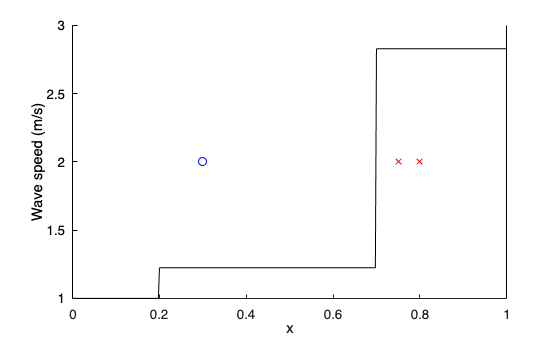

plotAcqGeo(wspeed,mps,gridSp_single);

% Initialize solver
solver_single = AcousticSolver1D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_single,t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P_single,~] = solver_single.solve(p0,v0,Source=source);

In the case of a single receiver, we visualize the output data as a plot of the field (e.g., pressure) versus time.

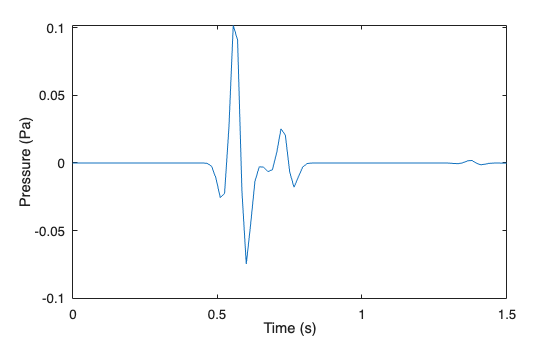

P_single.plotTimeSeries;

Here we specify a line of receivers, though not over the entire spatial domain.

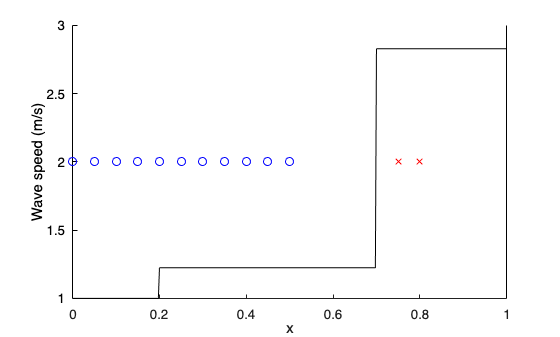

gridSp_line = GridSpace1D( Grid1DUnifPrimal([0,0.5],11) );

plotAcqGeo(wspeed,mps,gridSp_line);

Note that we initialize another solver for a different choice of receiver points.

% Initialize solver
solver_line = AcousticSolver1D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_line,t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P_line,~] = solver_line.solve(p0,v0,Source=source);

It is traditional to visualize time series data from receivers by time versus receiver index.

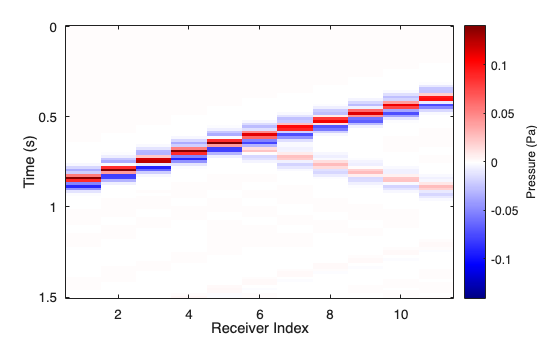

P_line.plotTimeSeries;